# Rocket State Estimator

Authors: John H. Lambert and Daniel J. Pearson

Version: 10/5/2023

clear variables; close all; clc;

### Initialization

% State Vector
x = [1; 0; 0; 0; 0; 0; 0; 0; 0; 0];
x_min = [1; 0; 0; 0; 0; 0; 0; 0; 0; 0];

P = eye(10); % Covariance Matrix
P_min = eye(10);

% R = diag([0.000262^2, 0.000262^2, 0.00262^2, 0.00262^2, 0.05^2, 0.05^2, 0.05^2, 0.05^2, 0.05^2, 0.05^2]); % Measurement Noise Covariance
R = diag([0.000262^2, 0.000262^2, 0.000262^2]);

Q = diag([0.01^2, 0.01^2, 0.01^2, 0.01^2, 0.01^2, 0.01^2, 0.01^2, 0.01^2, 0.01^2, 0.01^2]); % Process Noise Covariance

g = 9.81; % [m/s/s] Gravitational Acceleration 
m = 27.21; % [kg]

dt = 1/40; % [s]

### Rocket & Global Constants

rho = 1.22; % [kg/m^3] Air Density
S_r = (pi/4)*0.152^2; % [m^2] Rocket Cross Section
C_d = 0.4; % [] Guesstimated Value of Rocket CD

### Data Loading

% csvLog = readtable('Polaris_QuadTest_Log 2 (11-1-2023).csv');
csvLog = readtable('./data/IREC2023_FLASH_DATA.xlsx');

### Setup Live Plot

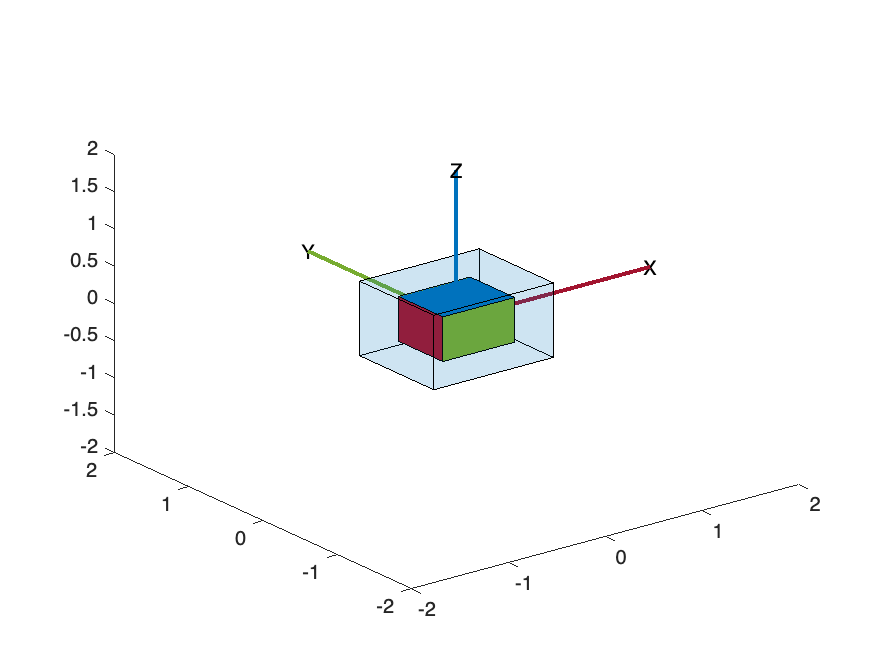

figure;
subplot(3,1,1);
accelPlot = plot(NaN, NaN);
xlabel('Time');
ylabel('m/s^2');
title('Acceleration (Z)');
subplot(3,1,2);
velZPlot = plot(NaN, NaN);
xlabel('Time');
ylabel('m/s');
title('Velocity (Z)');
subplot(3,1,3);
altPlot = plot(NaN, NaN);
title('Altitude');
xlabel('Time');
ylabel('m')

figure;
ax = axes;
view(3);  % Set the view to 3D
hold on;

pp = poseplot('Parent', gca);

## Setup UDP

serverIP = '127.0.0.1';
serverPort = 18550;
% udpClient = udpport("IPV4");

### Estimation Loop

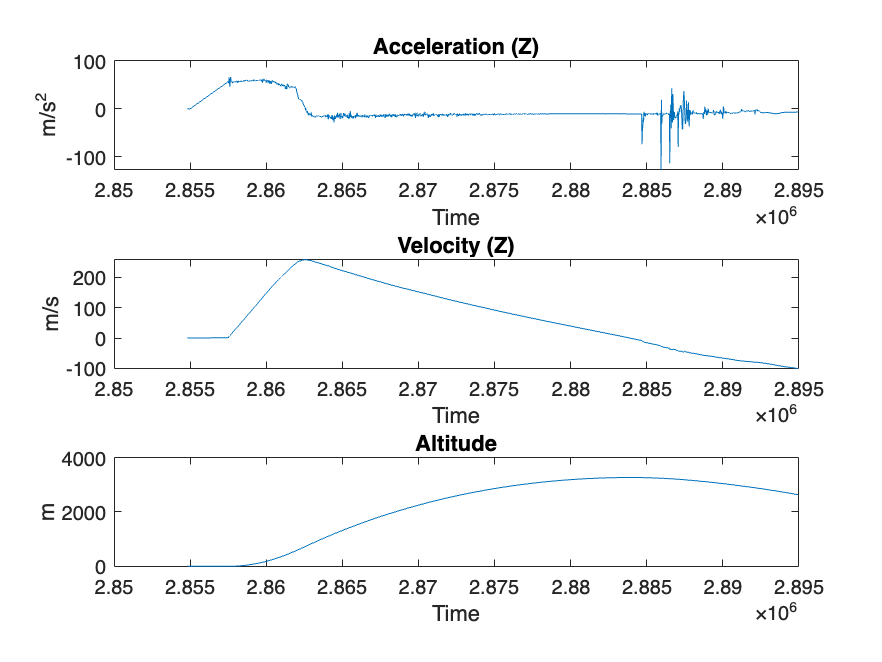

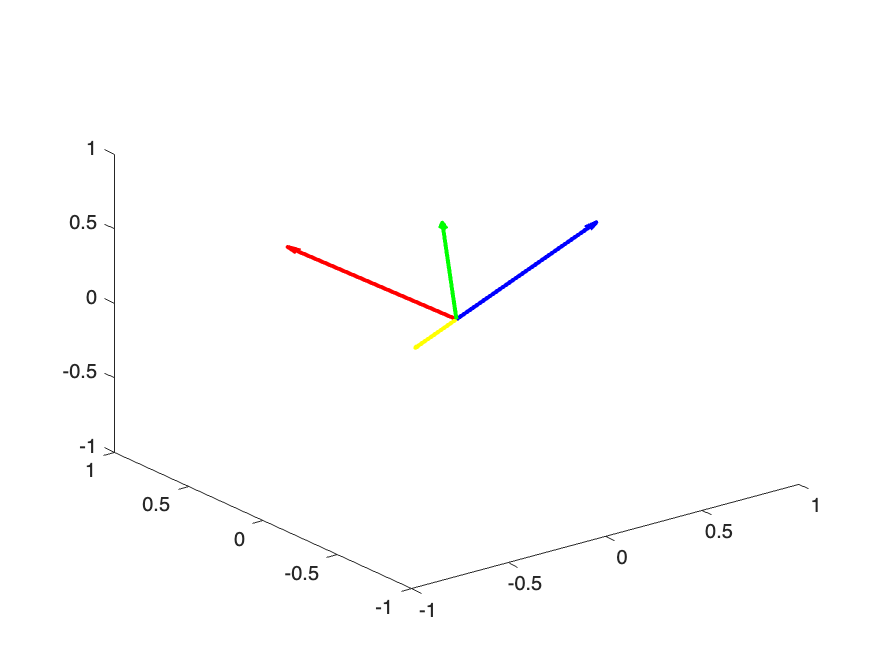

for i = 1:size(csvLog)
    % Apply conversion factor on Telemetry Log to de-compress data
    % Compression Factor - 10.0
    gyroX = (csvLog.GyroX(i) / 10.0) * (pi/180); % [rad/s]
    gyroY = (csvLog.GyroY(i) / 10.0) * (pi/180); % [rad/s]
    gyroZ = (csvLog.GyroZ(i) / 10.0) * (pi/180); % [rad/s]

    %% Apply conversion factor to Telemetry Log to de-compress data
    % Compression Factor - 100.0
    accelX = (csvLog.AccelX(i) / 100.0) * 9.81; % [m/s/s]
    accelY = (csvLog.AccelY(i) / 100.0) * 9.81; % [m/s/s]
    accelZ = ((csvLog.AccelZ(i) / 100.0) + 1) * 9.81; % [m/s/s]

    altitude = csvLog.Altitude(i);

    y = [accelX; accelY; accelZ];

    % Take quaternion from state and calculate rotation matrix
    axesRot = quat2rotm(x(1:4)');

    % Use the rotation matrix to obtain grav compensated global accel
    linearAccel = axesRot * y;
    linearAccel = linearAccel - [0;0;g];

    u = [gyroX; gyroY; gyroZ; linearAccel(1); linearAccel(2); linearAccel(3)];

    % x_min = x + dt*f(x, u);
    x_min = f(x,u,dt);

    A = calculate_Jacobian_f(x_min, u, dt);

    % P_min = P_min + A * P * A' + dt*Q;
    P_min = A*P*A' + dt*Q;

    h = h_func(x(1:4), y);

    C = calculate_Jacobian_h(x, y);

    K = P_min*C' / (C*P_min*C' + R);

    % x = x_min + K * (y - h);
    x = x_min;
    
    P = (eye(10) - K * C) * P_min;

    % Calculate Drag Force and Plot
    Fd = -(0.5)*rho*(sqrt(x(8)^2+x(9)^2+x(10)^2)^2*C_d*S_r);

    Fd = Fd/m/g;

    q = [x(1);x(2);x(3);x(4)];
    q_conj = [x(1);-x(2);-x(3);-x(4)];
    Fd_v = axesRot * [0;0;Fd];

    g_v = (axesRot * y) - Fd_v;

    % byteBuffer = typecast(single(q), 'uint8');
    % 
    % % write(udpClient, quaternionBytes);
    % write(udpClient,byteBuffer,"uint8", serverIP, serverPort);


    % Get the direction vectors for the axes
    x_axis = axesRot(:, 1);
    y_axis = axesRot(:, 2);
    z_axis = axesRot(:, 3);

    origin = [0 0 0];

    % Define the length of the axes
    axis_length = 1.0;

    cla(ax);

    % Plot the axes using quiver3
    quiver3(origin(1), origin(2), origin(3), x_axis(1)*axis_length, x_axis(2)*axis_length, x_axis(3)*axis_length, 'r', 'LineWidth', 2);
    quiver3(origin(1), origin(2), origin(3), y_axis(1)*axis_length, y_axis(2)*axis_length, y_axis(3)*axis_length, 'g', 'LineWidth', 2);
    quiver3(origin(1), origin(2), origin(3), z_axis(1)*axis_length, z_axis(2)*axis_length, z_axis(3)*axis_length, 'b', 'LineWidth', 2);
    % quiver3(origin(1), origin(2), origin(3), linearAccel(1), linearAccel(2), linearAccel(3), 'y', 'LineWidth', 2);
    quiver3(origin(1), origin(2), origin(3), Fd_v(1), Fd_v(2), Fd_v(3), 'y', 'LineWidth', 2);

    % Set axis limits as needed
    axis([-1 1 -1 1 -1 1]); % Adjust as needed

    angles = quat2eul(x(1:4)');

    currentTime = csvLog.Timestamp(i);

    x_data = get(accelPlot, 'XData');
    accelData = get(accelPlot, 'YData');
    altData = get(altPlot, 'YData');
    velZData = get(velZPlot, 'YData');

    x_data = [x_data, currentTime];
    accelData = [accelData, linearAccel(3)];
    altData = [altData, x(7)];
    velZData = [velZData, x(10)];

    set(accelPlot, 'XData', x_data, 'YData', accelData);
    set(altPlot, 'XData', x_data, 'YData', altData);
    set(velZPlot, 'XData', x_data, 'YData', velZData);

    pause(dt);
    % Refresh the plot
    drawnow;
end

function A = calculate_Jacobian_f(x, u, dt)
%calculate_jacobian - Calculate the jacobian of the f matrix
    q0 = x(1);
    q1 = x(2);
    q2 = x(3);
    q3 = x(4);

    p = u(1);
    q = u(2);
    r = u(3);
    ax = u(4);
    ay = u(5);
    az = u(6);

    A = [
        1 -0.5*dt*p -0.5*dt*q -0.5*dt*r 0 0 0 0 0 0;
        0.5*dt*p 1 0.5*dt*r -0.5*dt*q 0 0 0 0 0 0;
        0.5*dt*q -0.5*dt*r 1 0.5*dt*p 0 0 0 0 0 0;
        0.5*dt*r 0.5*dt*q -0.5*dt*p 1 0 0 0 0 0 0;
        0 0 0 0 1 0 0 dt 0 0;
        0 0 0 0 0 1 0 0 dt 0;
        0 0 0 0 0 0 1 0 0 dt;
        0 0 0 0 0 0 0 1 0 0;
        0 0 0 0 0 0 0 0 1 0;
        0 0 0 0 0 0 0 0 0 1;
    ];
end

function C = calculate_Jacobian_h(x, y)
    % Extract quaternion components from the state vector x
    q0 = x(1);
    q1 = x(2);
    q2 = x(3);
    q3 = x(4);

    % Normalize the quaternion to ensure it represents a valid rotation
    q_norm = norm([q0, q1, q2, q3]);
    q0 = q0 / q_norm;
    q1 = q1 / q_norm;
    q2 = q2 / q_norm;
    q3 = q3 / q_norm;

    % C = [
    % -2*q3*(y(2)-y(1)) 2*(q2*y(2)+q3*y(3)) 2*(q1*y(2)-2*q2*y(1)) y(3)*(2*q1+2*q0)-4*q3*y(1)-2*q0*y(2);
    % 2*q3*(y(1)-y(3)) 2*(q2*y(1)-2*q1*y(2)) 2*(q1*y(1)+q3*y(3)) y(3)*(2*q2-2*q0)-4*q3*y(2)+2*q0*y(1);
    % 2*(q1*y(2)-q2*y(1)) 2*(q3*y(1)-2*q1*y(3)+q0*y(2)) 2*(q3*y(2)-q0*y(1)) 2*(q1*y(1)+q2*y(2)-2*q3*y(1));
    % ];

    % % Calculate the Jacobian matrix C
    C = zeros(3, 10); % Initialize the Jacobian matrix

    % Calculate the elements of the Jacobian matrix C
    C(1, 1) = -2 * (q2 * y(3) - q3 * y(2));
    C(1, 2) = 2 * (q1 * y(3) + q3 * y(1));
    C(1, 3) = -2 * (q1 * y(2) - q2 * y(1));

    C(2, 1) = 2 * (q2 * y(3) - q3 * y(2));
    C(2, 2) = -2 * (q1 * y(3) + q3 * y(1));
    C(2, 3) = 2 * (q1 * y(2) + q2 * y(1));

    C(3, 1) = -2 * (q1 * y(3) + q2 * y(2));
    C(3, 2) = 2 * (q2 * y(1) - q1 * y(2));
    C(3, 3) = 0;

    % Normalize the Jacobian matrix to account for the quaternion normalization
    C = C / q_norm;
end

function h = h_func(q, y)
%f - Helper function to calculate the h update matrix to transform
%accelerations into the global frame using the orienatation

    q = q / norm(q); % Normalize Quaternion
    
    % Quaternion Rotation Matrix
    Rot = [1 - 2*(q(3)^2 + q(4)^2), 2*(q(2)*q(3) - q(1)*q(4)), 2*(q(2)*q(4) + q(1)*q(3));
         2*(q(2)*q(3) + q(1)*q(4)), 1 - 2*(q(2)^2 + q(4)^2), 2*(q(3)*q(4) - q(1)*q(2));
         2*(q(2)*q(4) - q(1)*q(3)), 2*(q(3)*q(4) + q(1)*q(2)), 1 - 2*(q(2)^2 + q(3)^2)];

    h = Rot * y;
end

function dx = f(x, u, dt)
%f - Helper function to calculate the eulerian rate using the body
%orientation and control inputs of the system
    p = u(1);
    q = u(2);
    r = u(3);
    ax = u(4);
    ay = u(5);
    az = u(6);

    dq = [
      x(1) - (dt/2)*p*x(2) - (dt/2)*q*x(3) - (dt/2)*r*x(4);
      x(2) + (dt/2)*p*x(1) - (dt/2)*q*x(4) + (dt/2)*r*x(3);
      x(3) + (dt/2)*p*x(4) + (dt/2)*q*x(1) - (dt/2)*r*x(2);
      x(4) - (dt/2)*p*x(3) + (dt/2)*q*x(2) + (dt/2)*r*x(1);
    ];

    % Normalize Quaternion Derivative
    dq = dq / norm(dq);

    dv = [
        x(8) + (dt)*ax;
        x(9) + (dt)*ay;
        x(10) + (dt)*az;
    ];

    dp = [
        x(5) + x(8)*dt;
        x(6) + x(9)*dt;
        x(7) + x(10)*dt;
    ];
    
    dx = [
        dq;
        dp;
        dv;
    ];

    % Quaternion Derivative
    % dqdp = [
    %         0 -0.5*p -0.5*q -0.5*r 0 0 0 0 0 0;
    %         0.5*p 0 0.5*r -0.5*q 0 0 0 0 0 0;
    %         0.5*q -0.5*r 0 0.5*p 0 0 0 0 0 0;
    %         0.5*r 0.5*q -0.5*p 0 0 0 0 0 0 0;
    %         0 0 0 0 0 0 0 1 0 0;
    %         0 0 0 0 0 0 0 0 1 0;
    %         0 0 0 0 0 0 0 0 0 1;
    %         0 0 0 0 0 0 0 0 0 0;
    %         0 0 0 0 0 0 0 0 0 0;
    %         0 0 0 0 0 0 0 0 0 0;
    %     ] * x;
    % 
    % dx = dqdp + [0;0;0;0;0;0;0;ax;ay;az];
   
end